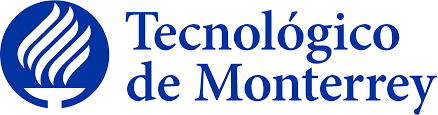

## Implementación de robótica inteligente (TE3002B)

## Actividad 1.9 (Landmarks)

### Pamela Hernández Montero A01736368

**Indicaciones:**

Implementar el código requerido para generar el seguimiento de los siguientes waypoints (puntos de referencia), ajustando el tiempo de muestreo: “sampleTime”, vector de tiempo: “tVec”, pose inicial: “initPose”, y los waypoints: “waypoints”

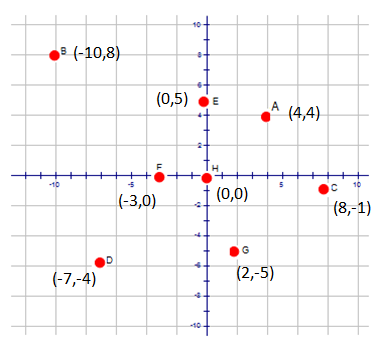

Para la primera trayectoria, el valor de sampleTime fue el mismos que en los ejemplos pasados. Sin embargo, la posición inicial en X y Y empezó desde el origen de posición del robot. En este caso, lo definí para el punto A, siguiendo consecutivamente los demás valores del abecedario hasta la H, donde cada punto se encuentra en el arreglo de waypoints

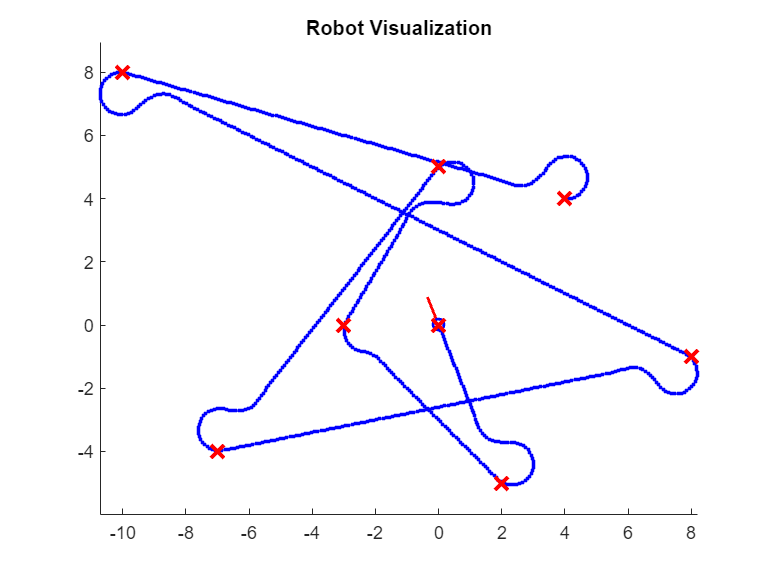

%% Define Vehicle
R = 0.1;                % Wheel radius [m]
L = 0.5;                % Wheelbase [m]
dd = DifferentialDrive(R,L);
%% Simulation parameters
sampleTime = 0.1;               % Sample time [s]
tVec = 0:sampleTime:91.3;         % Time array

initPose = [4;4;0];             % Initial pose (x y theta)
pose = zeros(3,numel(tVec));    % Pose matrix
pose(:,1) = initPose;

% Define waypoints
waypoints = [4,4;-10,8; 8,-1; -7,-4; 0,5; -3,0; 2,-5; 0,0];

% Create visualizer
viz = Visualizer2D;
viz.hasWaypoints = true;
%% Pure Pursuit Controller
controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.35;
controller.DesiredLinearVelocity = 1;
controller.MaxAngularVelocity = 1.5;
%% Simulation loop
close all
r = rateControl(1/sampleTime);
for idx = 2:numel(tVec) 
    % Run the Pure Pursuit controller and convert output to wheel speeds
    [vRef,wRef] = controller(pose(:,idx-1));
    [wL,wR] = inverseKinematics(dd,vRef,wRef);
 
    
    % Compute the velocities
    [v,w] = forwardKinematics(dd,wL,wR);
    velB = [v;0;w]; % Body velocities [vx;vy;w]
    vel = bodyToWorld(velB,pose(:,idx-1));  % Convert from body to world
    
    % Perform forward discrete integration step
    pose(:,idx) = pose(:,idx-1) + vel*sampleTime; 
    
    % Update visualization
    viz(pose(:,idx),waypoints);
    waitfor(r);
end

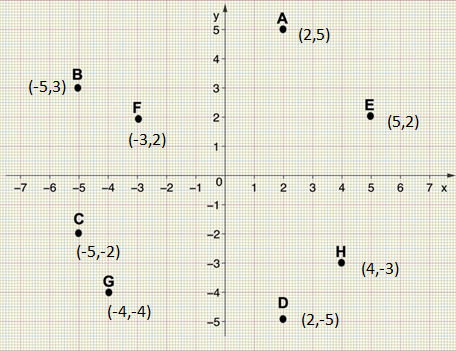

Para la siguiente trayectoria, el valor de sampleTime fue el mismo. Sin embargo, la posición inicial en X y Y se ubicó en el punto A con las coordenadas (2,5) y una orientacion (5*pi)/6 para disminuir el timpo de simulación, siguiendo consecutivamente los demás valores del abecedario hasta la H, donde cada punto se encuentra en el arreglo de waypoints.

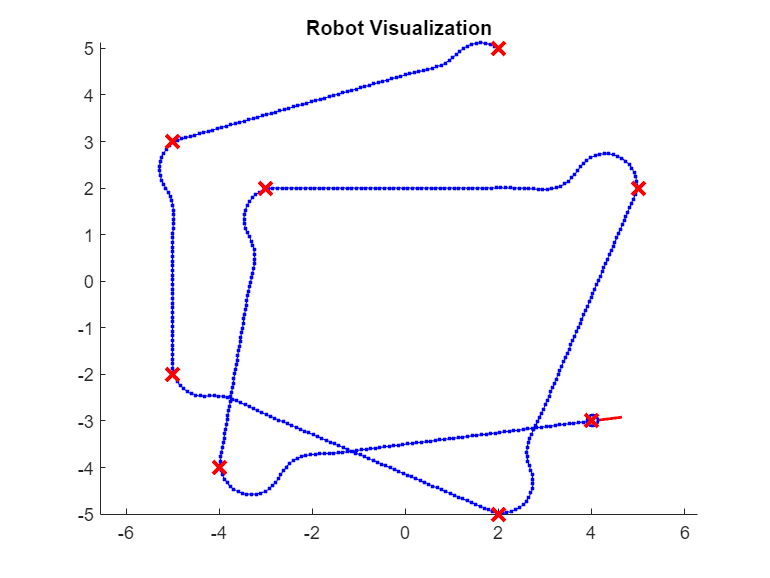

%% Define Vehicle
R = 0.1;                % Wheel radius [m]
L = 0.5;                % Wheelbase [m]
dd = DifferentialDrive(R,L);
%% Simulation parameters
sampleTime = 0.1;               % Sample time [s]
tVec = 0:sampleTime:51.8;          % Time array
initPose = [2;5;(5*pi)/6];             % Initial pose (x y theta)
pose = zeros(3,numel(tVec));    % Pose matrix
pose(:,1) = initPose;

% Define waypoints
waypoints = [2,5; -5,3; -5,-2; 2,-5; 5,2; -3,2; -4,-4; 4,-3];

% Create visualizer
viz = Visualizer2D;
viz.hasWaypoints = true;
%% Pure Pursuit Controller
controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.35;
controller.DesiredLinearVelocity = 1;
controller.MaxAngularVelocity = 1.5;
%% Simulation loop
close all
r = rateControl(1/sampleTime);
for idx = 2:numel(tVec) 
    % Run the Pure Pursuit controller and convert output to wheel speeds
    [vRef,wRef] = controller(pose(:,idx-1));
    [wL,wR] = inverseKinematics(dd,vRef,wRef);
 
    
    % Compute the velocities
    [v,w] = forwardKinematics(dd,wL,wR);
    velB = [v;0;w]; % Body velocities [vx;vy;w]
    vel = bodyToWorld(velB,pose(:,idx-1));  % Convert from body to world
    
    % Perform forward discrete integration step
    pose(:,idx) = pose(:,idx-1) + vel*sampleTime; 
    
    % Update visualization
    viz(pose(:,idx),waypoints);
    waitfor(r);
end

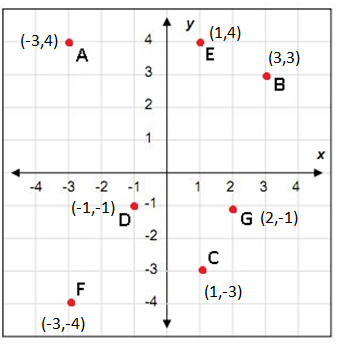

Por último se definió una serie de waypoints más pequeña que abarcaba de A a G, cuyo origen era (-3,4) y tiempo de simulación de 40.7.

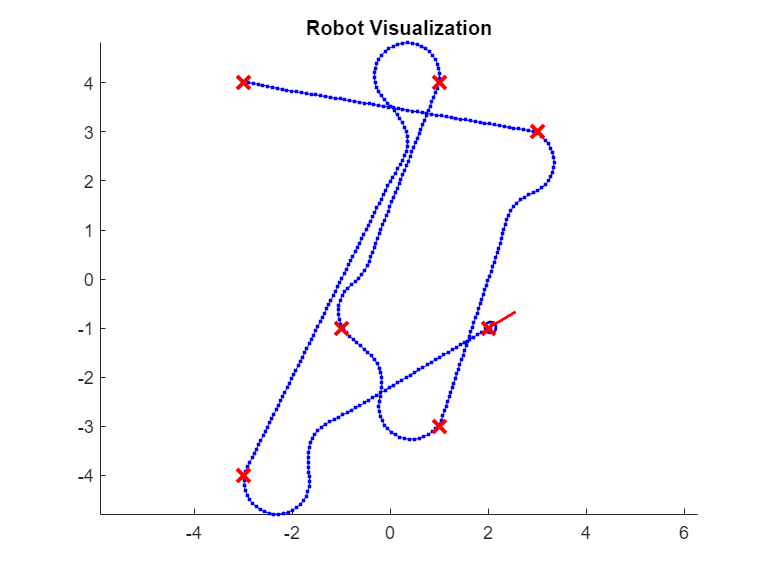

%% Define Vehicle
R = 0.1;                % Wheel radius [m]
L = 0.5;                % Wheelbase [m]
dd = DifferentialDrive(R,L);
%% Simulation parameters
sampleTime = 0.1;               % Sample time [s]
tVec = 0:sampleTime:40.7;          % Time array

initPose = [-3;4;0];             % Initial pose (x y theta)
pose = zeros(3,numel(tVec));    % Pose matrix
pose(:,1) = initPose;

% Define waypoints
waypoints = [-3,4; 3,3; 1,-3; -1,-1; 1,4; -3,-4; 2,-1];

% Create visualizer
viz = Visualizer2D;
viz.hasWaypoints = true;
%% Pure Pursuit Controller
controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.35;
controller.DesiredLinearVelocity = 1;
controller.MaxAngularVelocity = 1.5;
%% Simulation loop
close all
r = rateControl(1/sampleTime);
for idx = 2:numel(tVec) 
    % Run the Pure Pursuit controller and convert output to wheel speeds
    [vRef,wRef] = controller(pose(:,idx-1));
    [wL,wR] = inverseKinematics(dd,vRef,wRef);
 
    
    % Compute the velocities
    [v,w] = forwardKinematics(dd,wL,wR);
    velB = [v;0;w]; % Body velocities [vx;vy;w]
    vel = bodyToWorld(velB,pose(:,idx-1));  % Convert from body to world
    
    % Perform forward discrete integration step
    pose(:,idx) = pose(:,idx-1) + vel*sampleTime; 
    
    % Update visualization
    viz(pose(:,idx),waypoints);
    waitfor(r);
    
end

**Conclusión**

La implementación del seguimiento de trayectorias resultó relativamente sencilla de determinar, ya que solo implicó modificar los valores de orientación, coordenadas iniciales y waypoints. No obstante, la parte más laboriosa fue ajustar los tiempos de simulación exactos. Esto se debió a que requería un proceso de prueba y error para encontrar los valores adecuados, lo que prolongó el tiempo de implementación. 